# df

rna = readtable('final_sel_feat_mrna.xlsx', 'ReadRowNames',true);
save('final_sel_feat_mrna.mat', 'rna')
mut = readtable('final_sel_feat_mut.xlsx', 'ReadRowNames',true);
save('final_sel_feat_mut.mat', 'mut')
meth = readtable('final_sel_feat_meth.xlsx', 'ReadRowNames',true);
save('final_sel_feat_meth.mat', 'meth')
cnv = readtable('final_sel_feat_cnv.xlsx', 'ReadRowNames',true);
save('final_sel_feat_cnv.mat', 'cnv')
DR=readtable('DR_100-screened_drugs_imputed.xlsx', "ReadRowNames",true);
save('drug_resp.mat', 'DR')
clear

load("final_sel_feat_cnv.mat");
load("final_sel_feat_mrna.mat")
load("final_sel_feat_mut.mat");
load("final_sel_feat_meth.mat");
load("drug_resp.mat");
CNV = (table2array(cnv))';
RNA = (table2array(rna))';

mutation = (table2array(mut))';
methylation = (table2array(meth))';
% clinical = (table2array(clinical))';
t = (table2array(DR))';
x= {CNV; RNA; mutation; methylation};

%rng(0,'twister'); % For reproducibility
% N = 100;
% targets = rand(30,10)';
% input1 = rand(N,30);
% input2 = rand(N,30);

rng(1);
k=5;
cvnn = cvpartition(t(1,:),'KFold',k)

cvnn = K-fold cross validation partition
   NumObservations: 42
       NumTestSets: 5
         TrainSize: 34  33  33  34  34
          TestSize: 8  9  9  8  8


hiddenLayerSize = [11 11];
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.
net = fitnet(hiddenLayerSize, trainFcn);
net.performFcn = 'mse'; 

net.performParam.normalization = 'none';
net.performParam.regularization =0.3743;
net.performParam.regularization

ans = 0.3743

ans =     14    17    37    25    20    38    41    29     1    36    33    12    27    15    11    26    39     8     3    10    24     5    30    23    40     7     9     4


ans =     21     2    22    35    34    19


ans =      6    13    16    18    28    31    32    42


performance = 1.4241

mseError = 2.2126

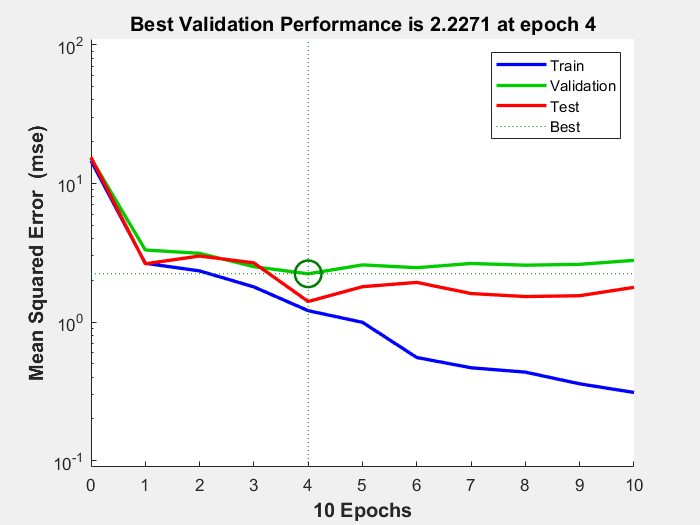

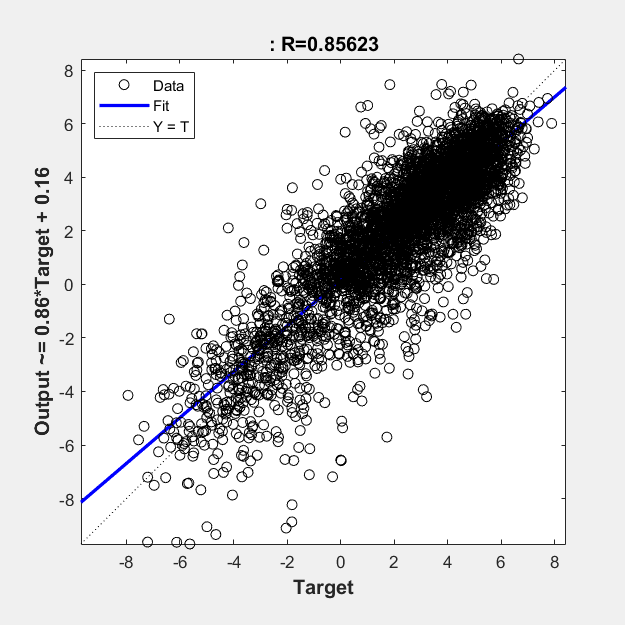

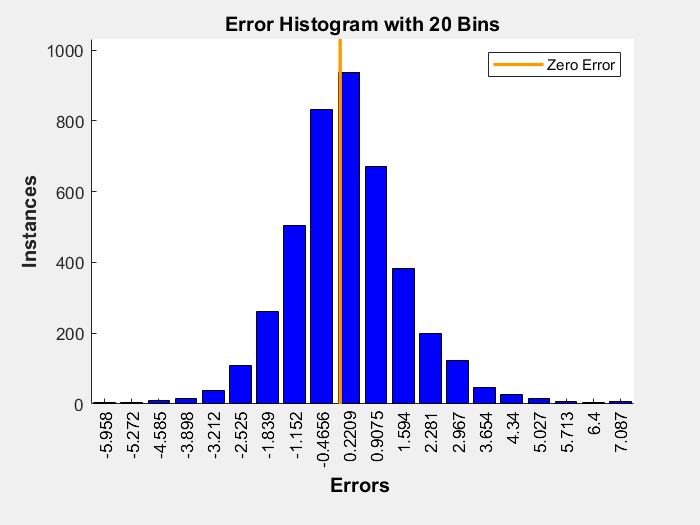

ans =     12    13     2    10    21    20     3    14    31    30    36    32    42     5    37    16    26     6    22    39    38     1    18    29    25     4    33    15


ans =     35    28     8    34    11


ans =      7     9    17    19    23    24    27    40    41


performance = 0.7499

mseError = 1.1545

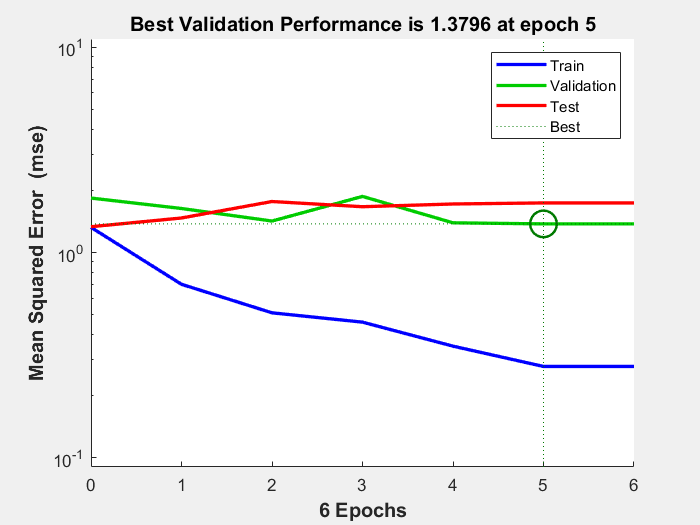

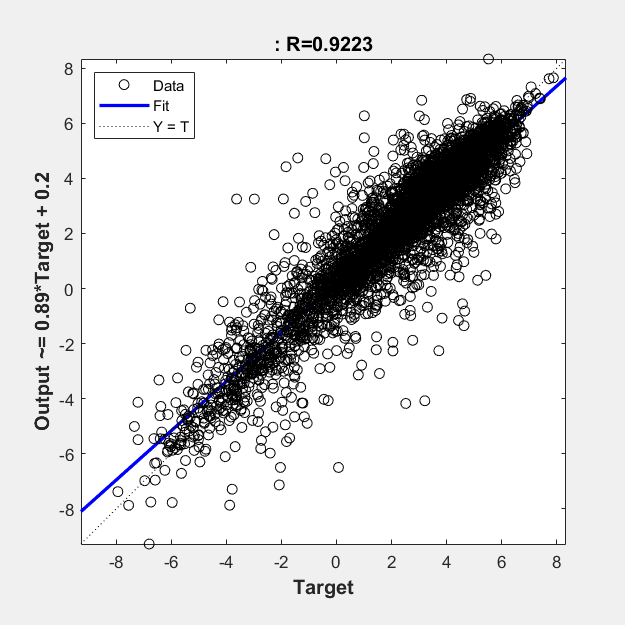

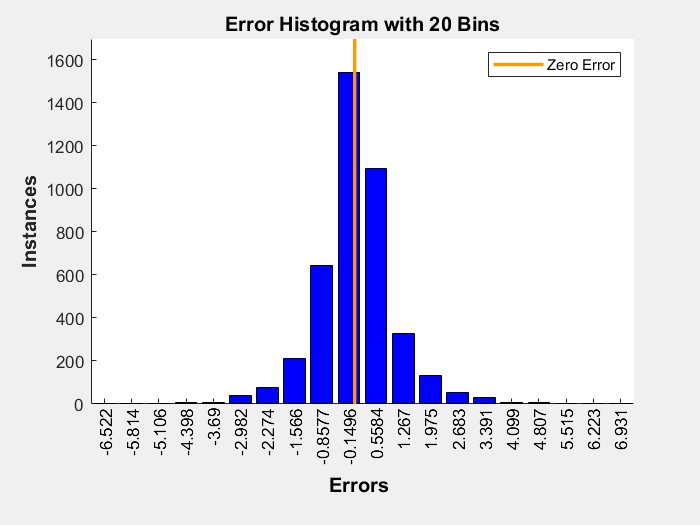

ans =     22    32     5     1    35    41    16    31    24    38    39    17    18    27    19    28    13    25    26    10    33    42    21    34    23    11     9     2


ans =     15    14    40     7     6


ans =      3     4     8    12    20    29    30    36    37


performance = 0.7499

mseError = 1.1545

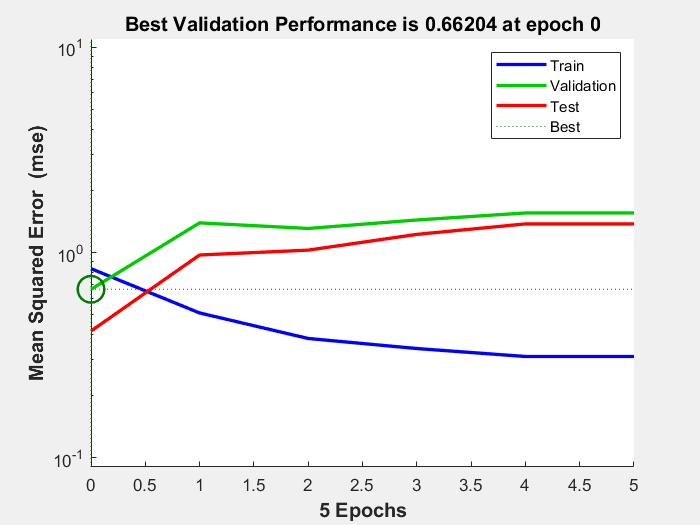

ans =     27    17    13    36    33    28    24    19    37    14    23     4    41     5    18    25    16     9    40     7     3    12    31    10     8    26    42    29


ans =     34    30    20    32    35     6


ans =      1     2    11    15    21    22    38    39


performance = 0.7499

mseError = 1.1545

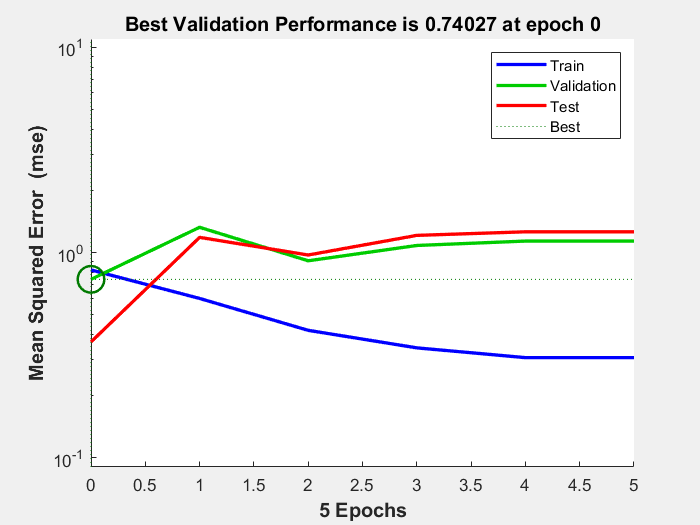

ans =     20     1    11    24    28     8    39     9     2    19    17    41    27    30    32    29    21    31    15    12    22    40     3    16    37    38    18    42


ans =     13     7    36     6     4    23


ans =      5    10    14    25    26    33    34    35


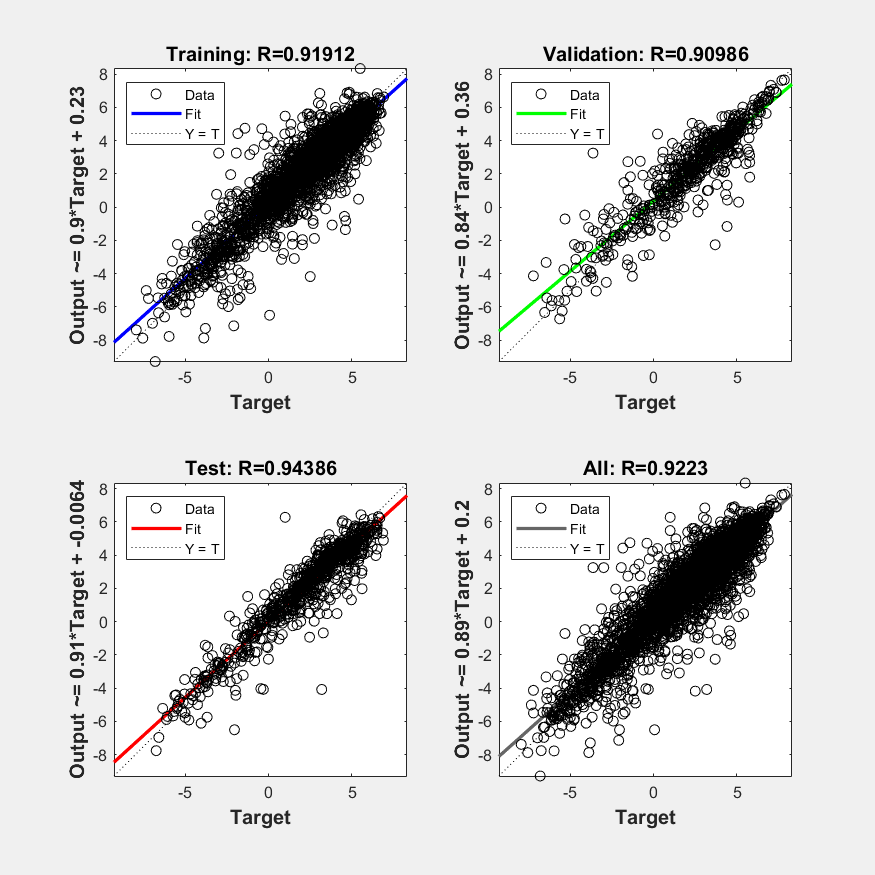

performance = 0.7499

mseError = 1.1545

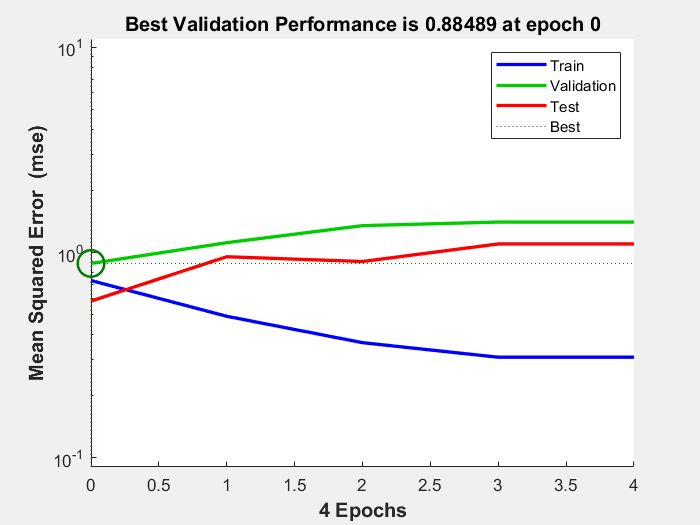

for i=1:k
      testIdx = cvnn.test(i);               %# get indices of test instances
      trainIdx = cvnn.training(i) ;                  %# get indices training instances
      trInd = find(trainIdx);
      tstInd = find(testIdx);
      trInd_r = trInd(randperm(length(trInd)));
      ind1=(vertcat(trInd_r,tstInd))'; 
      Q1=length(trInd_r);
      Q2=length(tstInd);
     
      net.divideFcn = 'divideind'; 
      [net.divideParam.trainInd, net.divideParam.valInd, net.divideParam.testInd] = divideind(ind1,1:28,28:Q1,Q1+(1:Q2));
      net.divideParam.trainInd
      net.divideParam.valInd
      net.divideParam.testInd
      net.numinputs = 4;
      net.inputConnect = [1 1 1 1;0 0 0 0;0 0 0 0];
      %net.inputConnect = [1 1 1 1; 0 0 0 0];
      
      %train the network
      [net,tr] = train(net,x,t);
      
    
   
      y = net(x);
      y=cell2mat(y);
      e = gsubtract(t,y);
      performance = perform(net,t,y)
      %ypred=cell2mat(y);
      mseError = mse(t-y)
      figure, plotperform(tr);
      figure, plotregression(t,y);
      figure, ploterrhist(e);
      %disp(mseError)      
end

## save